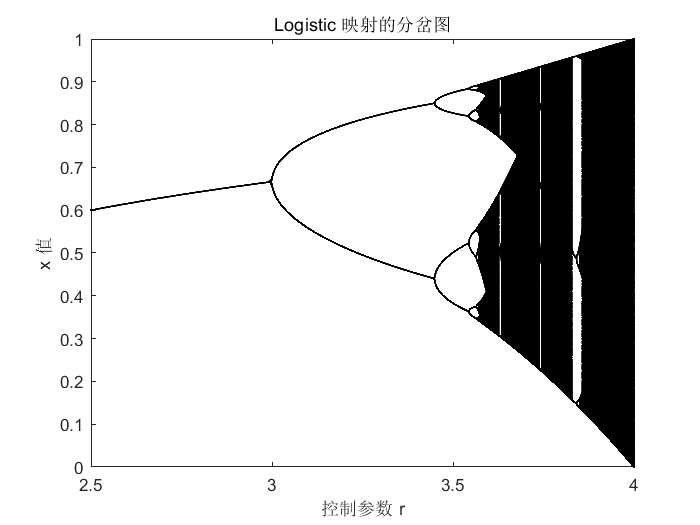

clc;clear all;close all;
% Logistic映射的分岔图
% 参数范围和初始化
r_min = 2.5;     % 控制参数r的最小值
r_max = 4.0;     % 控制参数r的最大值
num_r = 10000;    % r的采样点数量
N = 1000;        % 总迭代次数
nSkip = 500;     % 跳过前nSkip次迭代，以排除初始条件的影响

% 初始化r的值和保存分岔图的x值
r_values = linspace(r_min, r_max, num_r); % r从r_min到r_max的采样点
x_vals = zeros(num_r, N - nSkip); % 存储分岔图中的x值

% 遍历每个r值，计算对应的Logistic映射
for i = 1:num_r
    r = r_values(i);   % 当前r值
    x = 0.5;           % 初始条件
    
    % 进行N次迭代
    for n = 1:N
        x = r * x * (1 - x); % Logistic映射公式
        % 跳过前nSkip次迭代，保存后续的值
        if n > nSkip
            x_vals(i, n - nSkip) = x;
        end
    end
end

% 绘制分岔图
figure;
plot(r_values, x_vals, '.k', 'MarkerSize', 0.1);
xlabel('控制参数 r');
ylabel('x 值');
title('Logistic 映射的分岔图');
axis([r_min, r_max, 0, 1]);